## **RT-QIBC analysis of cells treated with MLN-4924 (with siGeminin) **

**Variables:**

FarRed = mean EdU intensity within nucleus

RFP = mean chromatin-bound PCNA intensity within nucleus

POI_time(:,2) = time since APC/C inactivation

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    'siCtrl DMSO ',2:3,2:6,1:4,[0 0 0]; %1
    'siCtrl MLN ',4:5,2:6,1:4,[0 0 0]; %2
    'siGMNN DMSO ',2:3,7:11,1:4,[0 0 0]; %1
    'siGMNN MLN ',4:5,7:11,1:4,[0 0 0]; %2
    };


load([dataDir 'E1086_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 74;
timeStart = 0;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;
times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

colors =  [0    0.4470    0.7410;
    0.8500    0.3250    0.0980;
    0.9290    0.6940    0.1250;
    0.4940    0.1840    0.5560;
    0.4660    0.6740    0.1880;
    0.3010    0.7450    0.9330;
    0.6350    0.0780    0.1840];


**Check stains**

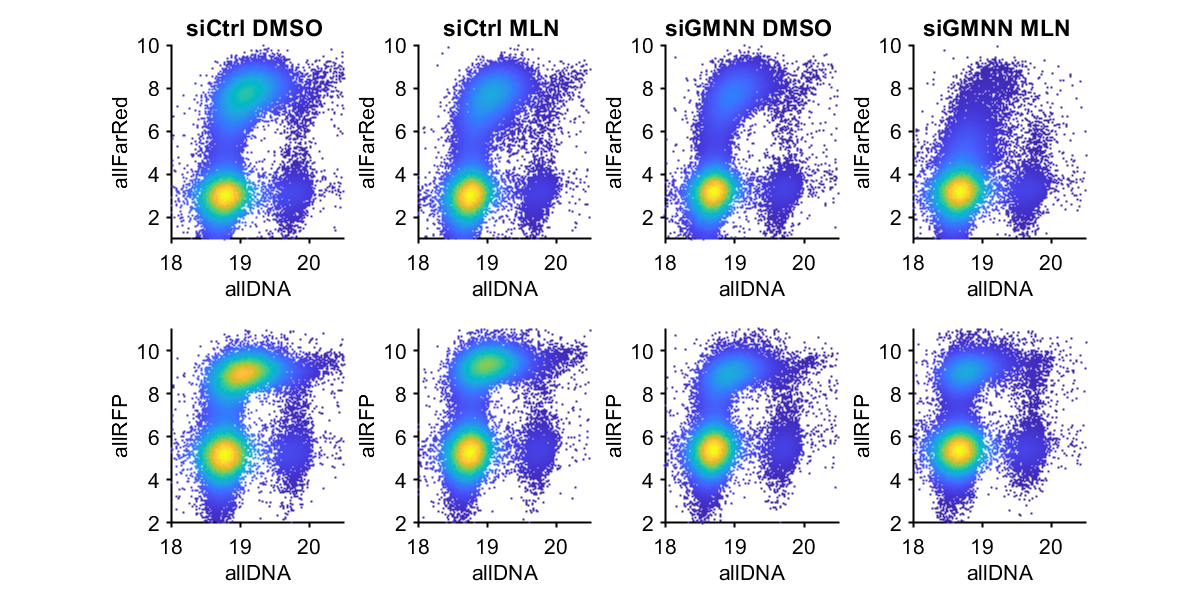

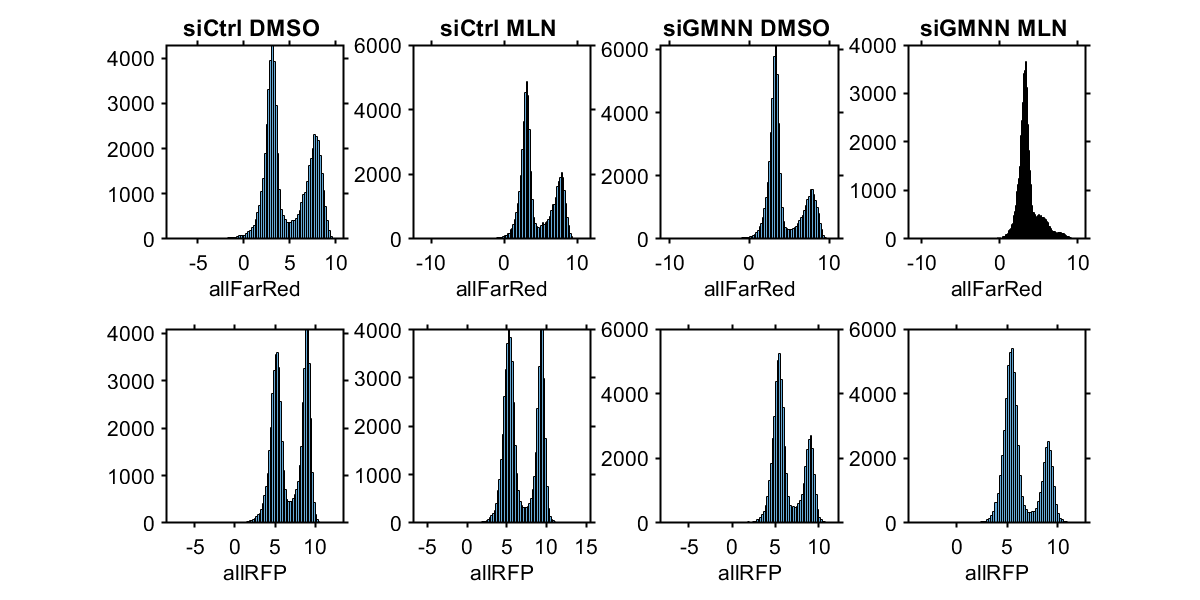

conds=[1 2 3 4];

xval = 'allDNA';
yval = 'allFarRed';
zval = 'allRFP';

f1 = figure('pos',[0 0 300*length(conds) 600]);
f2 = figure('pos',[0 0 300*length(conds) 600]);
for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  real(log2(S(condition).(yval)));
    zdata = real(log2(S(condition).(zval)));
    
    figure(f1)
    subplot(2,length(conds),i)
    dscatter(xdata,ydata);
    xlim([18 20.5])
    ylim([1 10]);
    ylabel(yval);
    xlabel(xval);
    title(conditions{condition,1});
    
    figure(f1)
    subplot(2,length(conds),i+length(conds))
    dscatter(xdata,zdata);
    xlim([18 20.5])
    ylim([2 11]);
    ylabel(zval);xlabel(xval);
    
    figure(f2)
    subplot(2,length(conds),i)
    histogram(ydata)
    xlabel(yval)
    title(conditions{condition,1});
    
    figure(f2)
    subplot(2,length(conds),i+length(conds))
    histogram(zdata)
    xlabel(zval)
end

**Set thresholds**

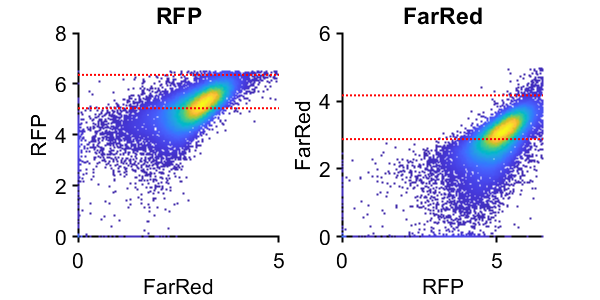


%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'RFP','FarRed'};
plotting = {'FarRed','RFP'};
prctiles = {[50 99], [50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = isnan(S(cond).POI_time(:,2)) & S(cond).dna < 2^19.25 & S(cond).RFP < 2^6.5 & S(cond).FarRed < 2^5;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    ydata(ydata < 1) = 1;
    xdata(xdata < 1) = 1;
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    
end

**PCNA vs EdU levels S cells**

ans = 72

ans = 1448

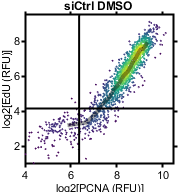

props =     9.7376    0.1381
   10.5663   79.5580


frac =     0.1172    0.8828


ans = 68

ans = 1369

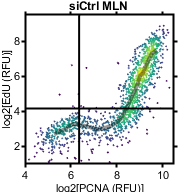

props =    20.0146    0.3652
   26.7348   52.8853


frac =     0.3358    0.6642


ans = 63

ans = 1268

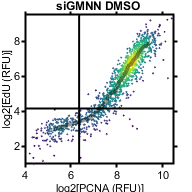

props =    17.4290         0
   12.6183   69.9527


frac =     0.1528    0.8472


ans = 60

ans = 1218

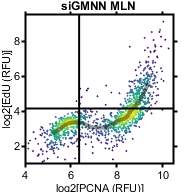

props =    31.1987    0.0821
   41.2151   27.5041


frac =     0.5998    0.4002


conds=[1 2 3 4];

xval = 'RFP';
yval = 'FarRed';

f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);

xdata_all = [];
ydata_all = [];
groups_all = [];

for i = 1:length(conds)
    condition = conds(i);
    xdata = real(log2(S(condition).(xval)));
    ydata =  real(log2(S(condition).(yval)));
    
    inds = S(condition).dna < 2^19.25 & S(condition).POI_time(:,2) < 3 & S(condition).POI_time(:,2) > 2 & S(condition).cdk(:,end) > .8;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    threshs ={{gate.FarRed_G1(2), 1}};
    %     edges = linspace(5,10,20);
    edges = prctile(xdata,5:5:95);
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc','std'},...
        'Threshs',threshs, 'Edges',edges);
    midpoints = edges;
    midpoints = (midpoints(1:end-1) + midpoints(2:end))/2 ;
    
    
    min(binData.numCells(binData.numCells >0))
    length(xdata)
    figure('Units', 'Inches', 'Position', [0, 0, 2, 2]), hold on
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    patchline(midpoints(binData(1).numCells > 10),binData(1).median(binData(1).numCells > 10),'LineWidth',3,'EdgeAlpha',.4)
    
    xdata_all = [xdata_all; xdata];
    ydata_all = [ydata_all; ydata];
    groups_all = [groups_all; repmat(categorical(conditions(condition,1)),size(xdata))];
    
    xlim([4 10.5])
    ylim([1 9.5])
    vline(log2(gate.RFP_G1(2)),'k');
    hline(log2(gate.FarRed_G1(2)),'k');
    axis square
    ylabel('log2[EdU (RFU)]');
    xlabel('log2[PCNA (RFU)]');
    set(gca,'FontSize',8)
    box on
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
    print_pdf([pwd() '\Figs\MLNPCNAvsEdU_' num2str(i) '.pdf'])
    
    figure(f1),hold on
    p = plot(midpoints(binData(1).numCells > 10),binData(1).median(binData(1).numCells > 10),'MarkerSize',4,'Marker','o','MarkerFaceColor','auto');
    %     p.MarkerFaceColor = p.Color;
    
    pcna_pos = xdata > log2(gate.RFP_G1(2));
    edu_pos = ydata > log2(gate.FarRed_G1(2));
    props = confusionmat(pcna_pos,edu_pos)/length(xdata) * 100
    frac = props(2,:)/sum(props(2,:))
    
end

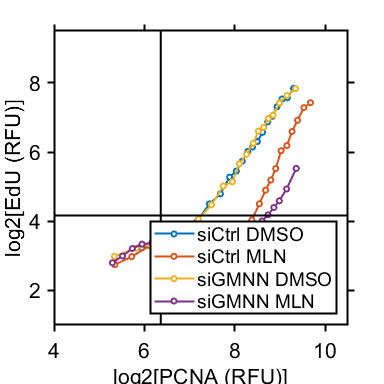


ylabel('log2[EdU (RFU)]');
xlabel('log2[PCNA (RFU)]');
xlim([4 10.5])
ylim([1 9.5])
vline(log2(gate.RFP_G1(2)),'k');
hline(log2(gate.FarRed_G1(2)),'k');
axis square
box on
legend(conditions(conds,1),'location','southeast');
print_pdf([pwd() '\Figs\MLNPCNAvsEdUcompare.pdf'])

**PCNA vs EdU levels  S cells**

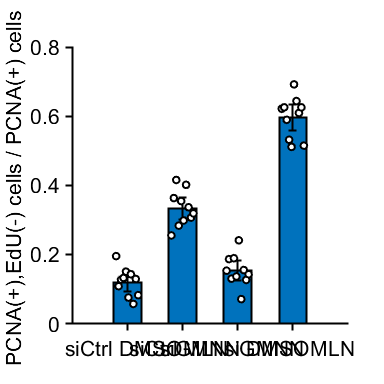

conds=[1 2 3 4];

xval = 'RFP';
yval = 'FarRed';

f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);

wellmean = [];
wellsem = [];
welldat = [];
cond_vec = [];

for i = 1:length(conds)
    condition = conds(i);
    xdata = real(log2(S(condition).(xval)));
    ydata =  real(log2(S(condition).(yval)));
    group = findgroups(categorical(string(num2str(S(condition).wellindex(:,[1 2])))));
    
    inds = S(condition).dna < 2^19.25 & S(condition).POI_time(:,2) < 3 & S(condition).POI_time(:,2) > 2 & S(condition).cdk(:,end) > .8;
    xdata = xdata(inds);
    ydata = ydata(inds);
    group = group(inds);
    
    
    pcna_pos = xdata > log2(gate.RFP_G1(2));
    edu_pos = ydata > log2(gate.FarRed_G1(2));
    pcna_pos_edu_neg = pcna_pos & ~edu_pos;
    %     sum(pcna_pos_edu_neg)/sum(pcna_pos)
    %     sum(pcna_pos_edu_neg)/length(pcna_pos_edu_neg)
    %
    dat = splitapply(@(x,y) sum(x)/sum(y), pcna_pos_edu_neg,pcna_pos,group);
    welldat =  [welldat dat];
    cond_vec = [cond_vec repmat(i,length(dat),1)];
    wellmean(i) = mean(dat);
    wellsem(i) = std(dat)/sqrt(length(dat));
end


figure('units','inches','position',[0 0 4 4])
hBar = bar(1:length(conds), wellmean,.5,'EdgeColor','k','LineWidth',1.5);
box off
hold on
errorbar(1:length(conds), wellmean, 2*wellsem, '+k','LineWidth',1.5)
axis square
set(gca,'XTickLabel',conditions(conds,1));
% xtickangle(45);
xlim([0 length(conds)+1])
% ylim([0 1])


jit = .2*linspace(-1,1,size(welldat,1));
xval_rep_jit = cond_vec + jit';
scatter(xval_rep_jit(:),welldat(:),25,'k','LineWidth',1.5,'MarkerFaceColor','w')
hold off
ylabel('PCNA(+),EdU(-) cells / PCNA(+) cells ');
print_pdf([pwd() '\Figs\compare_props.pdf'])


% [p,t,stats] = anova1(yvals(:),cond_vec(:));
% c = multcompare(stats);
h = [];
p = [];
groups = unique(cond_vec);
for i = 1:length(groups)
    for j = 1:length(groups)
        x1 = welldat(cond_vec == groups(i));
        x2 = welldat(cond_vec == groups(j));
        [h(i,j), p(i,j)] = ttest(x1(:),x2(:),'Alpha',0.05,'Tail','both');
    end
end
h

h =    NaN     1     0     1
     1   NaN     1     1
     0     1   NaN     1
     1     1     1   NaN


p

p =        NaN    0.0000    0.1775    0.0000
    0.0000       NaN    0.0001    0.0000
    0.1775    0.0001       NaN    0.0000
    0.0000    0.0000    0.0000       NaN
